# RandomSearch

Use random search to find optimal set of input parameters

clear all
% load pressure and temperature models
load('both_models.mat')

% set bounds
[hc_lower, hc_upper] = deal(0.6, 2.4);
[wc_lower, wc_upper] = deal(0.2, 1.8);
[L_lower, L_upper] = deal(12, 108);
[Tamb_lower, Tamb_upper] = deal(25, 31.6);
[Q_lower, Q_upper] = deal(1272, 5040);
[Uin_lower, Uin_upper] = deal(0, 20);

## Define Variables

% define the optimization parameters and ranges
optimVars = [
    optimizableVariable('hc', [hc_lower hc_upper], 'Type', 'real');
    optimizableVariable('wc', [wc_lower wc_upper], 'Type', 'real');
    optimizableVariable('L', [L_lower L_upper], 'Type', 'real');
    optimizableVariable('Tamb', [Tamb_lower Tamb_upper], 'Type', 'real');
    optimizableVariable('Q', [Q_lower Q_upper], 'Type', 'integer');
    optimizableVariable('Uin', [Uin_lower Uin_upper], 'Type', 'real');
];

## Define Objective and Constraints

Copying objective function to workers...
Done copying objective function to workers.
|===========================================================================================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | Constraint1  | Constraint2  |           hc |           wc |            L |         Tamb |            Q |          Uin |
|      | workers | result |             | runtime     | (observed)  |              |              |              |              |              |              |              |              |
|===========================================================================================================================================================================================|
|    1 |       1 | Infeas |       180.3 |     0.86603 |         NaN |           -1 |            1 |       2.0641 |       1.4754 |        55.44 |       27.5

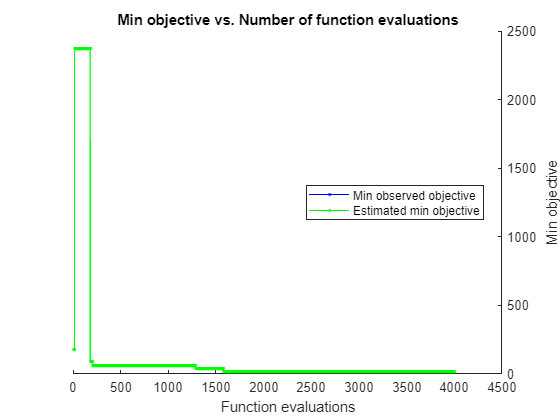


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 4000 reached.
Total function evaluations: 4005
Total elapsed time: 16281.7204 seconds
Total objective function evaluation time: 51.6333

Best observed feasible point:
      hc        wc         L        Tamb      Q        Uin  
    ______    _______    ______    ______    ____    _______

    1.1291    0.56109    29.232    27.335    1714    0.41621

Observed objective function value = 20.5013
Function evaluation time = 0.011752
Observed constraint violations =[ -1.000000 -1.000000 ]



% define Objective function
fun = @(T)objFcn(T, pressure_shallow_net, temp_shallow_net);

% run random search
results = bayesopt(fun,optimVars,...
   'AcquisitionFunctionName', 'random',...
   'MaxObjectiveEvaluations',4000,...
   'IsObjectiveDeterministic',true, ...
   'NumCoupledConstraints',2,...
   'UseParallel',true);

## Obtain best hyperparams

optimisedInputs = bestPoint(results)

optimisedInputs = 1×6 table
      hc        wc         L        Tamb      Q        Uin  
    ______    _______    ______    ______    ____    _______

    1.1291    0.56109    29.232    27.335    1714    0.41621


opt_ip = table2array(optimisedInputs)';
% Evaluate with the optimized inputs
pressure_drop = pressure_shallow_net(opt_ip)

pressure_drop = 20.5013

temperature = temp_shallow_net(opt_ip)

temperature = 56.3455

save('Run_2_random_4000.mat')

function [pressure_drop, constraints]= objFcn(T, press_net, temp_net)
    x_val = [T.hc; T.wc; T.L; T.Tamb; T.Q; T.Uin];
    pressure_drop = press_net(x_val);
    temperature = temp_net(x_val);
    
    % pressure constrain above 0
    if  pressure_drop >= 0
        pressure_lim = -1;  % feasible
    else 
        pressure_lim = 1;   % not feasible
    end

    % temp constrain btw 55 and 60
    if (temperature >= 55 && temperature <= 60)
        temp_range = -1;    % feasible
    else
        temp_range = 1;     % not feasible
    end
    constraints = [pressure_lim, temp_range];
end